clear; clc; close all;

features_1 = h5read("features_1.h5", "/DS1");
labels_1 = h5read("labels_1.h5", "/DS1");

split_idx = 84000;
X_Train = features_1(:, 1:split_idx);
Y_Train = labels_1(:, 1:split_idx);
X_Test = features_1(:, split_idx+1:end);
Y_Test = labels_1(:, split_idx+1:end);

Y_Train = categorical(Y_Train);
Y_Test = categorical(Y_Test);

dsTrain = MyDataStore(X_Train, Y_Train);
dsTest = MyDataStore(X_Test, Y_Test);
dsTrain, dsTest

dsTrain =   MyDataStore with properties:

    Features: [4032×84000 double]
      Labels: [5    11    0    10    5    8    7    6    9    6    8    0    7    11    0    0    11    8    10    10    6    8    3    1    10    4    7    10    2    6    4    10    5    1    7    5    2    2    4    8    2    11    11    6    …    ]


dsTest =   MyDataStore with properties:

    Features: [4032×16000 double]
      Labels: [3    1    9    0    5    3    10    8    11    6    6    6    7    6    9    4    5    4    10    0    8    7    7    1    3    9    1    9    3    0    3    10    0    9    10    5    5    11    8    6    11    5    7    2    …    ]


layers_G1 = [
    featureInputLayer(4032, "Normalization", "rescale-zero-one")
    fullyConnectedLayer(512)
    reluLayer
    fullyConnectedLayer(256)
    reluLayer
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(12)
    softmaxLayer
    classificationLayer
    ]

layers_G1 =   16×1 Layer array with layers:

     1   ''   Feature Input           4032 features with 'rescale-zero-one' normalization
     2   ''   Fully Connected         512 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         256 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         128 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         64 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         32 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         16 fully connected layer
    13   ''   ReLU                    ReLU
    14   ''   Fully Connected         12 fully connected layer
    15   ''   Softmax                 softmax
    16   ''   Classification Output   cr

layers_G2 = {};
for i = 1:6
    layers = [
        featureInputLayer(4032, "Normalization", "none")
        fullyConnectedLayer(512)
        reluLayer
        fullyConnectedLayer(256)
        reluLayer
        fullyConnectedLayer(128)
        reluLayer
        fullyConnectedLayer(64)
        reluLayer
        fullyConnectedLayer(32)
        reluLayer
        fullyConnectedLayer(16)
        reluLayer
        fullyConnectedLayer(5)
        softmaxLayer
        classificationLayer
        ];
    layers_G2{i} = layers;
end
layers_G2{1}

ans =   16×1 Layer array with layers:

     1   ''   Feature Input           4032 features
     2   ''   Fully Connected         512 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         256 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         128 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         64 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         32 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         16 fully connected layer
    13   ''   ReLU                    ReLU
    14   ''   Fully Connected         5 fully connected layer
    15   ''   Softmax                 softmax
    16   ''   Classification Output   crossentropyex

layers_G3 = {};
for i = 1:5
    layers = [
        featureInputLayer(4032, "Normalization", "none")
        fullyConnectedLayer(512)
        reluLayer
        fullyConnectedLayer(256)
        reluLayer
        fullyConnectedLayer(128)
        reluLayer
        fullyConnectedLayer(64)
        reluLayer
        fullyConnectedLayer(32)
        reluLayer
        fullyConnectedLayer(16)
        reluLayer
        fullyConnectedLayer(4)
        softmaxLayer
        classificationLayer
        ];
    layers_G3{i} = layers;
end
layers_G3{1}

ans =   16×1 Layer array with layers:

     1   ''   Feature Input           4032 features
     2   ''   Fully Connected         512 fully connected layer
     3   ''   ReLU                    ReLU
     4   ''   Fully Connected         256 fully connected layer
     5   ''   ReLU                    ReLU
     6   ''   Fully Connected         128 fully connected layer
     7   ''   ReLU                    ReLU
     8   ''   Fully Connected         64 fully connected layer
     9   ''   ReLU                    ReLU
    10   ''   Fully Connected         32 fully connected layer
    11   ''   ReLU                    ReLU
    12   ''   Fully Connected         16 fully connected layer
    13   ''   ReLU                    ReLU
    14   ''   Fully Connected         4 fully connected layer
    15   ''   Softmax                 softmax
    16   ''   Classification Output   crossentropyex

% Compile the model with specified loss function
options = trainingOptions('adam', ...
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'MiniBatchSize', 32, ...
    'Shuffle', 'every-epoch', ...
    'Plots', 'training-progress')

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 10
                   MiniBatchSize: 32
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironme

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |        9.38% |       2.5337 |          0.0100 |
|       1 |          50 |       00:00:03 |        3.12% |       2.5002 |          0.0100 |
|       1 |         100 |       00:00:05 |        6.25% |       2.4907 |          0.0100 |
|       1 |         150 |       00:00:07 |        9.38% |       2.4809 |          0.0100 |
|       1 |         200 |       00:00:08 |       12.50% |       2.4646 |          0.0100 |
|       1 |         250 |       00:00:10 |       12.50% |       2.4817 |          0.0100 |
|       1 |         300 |  

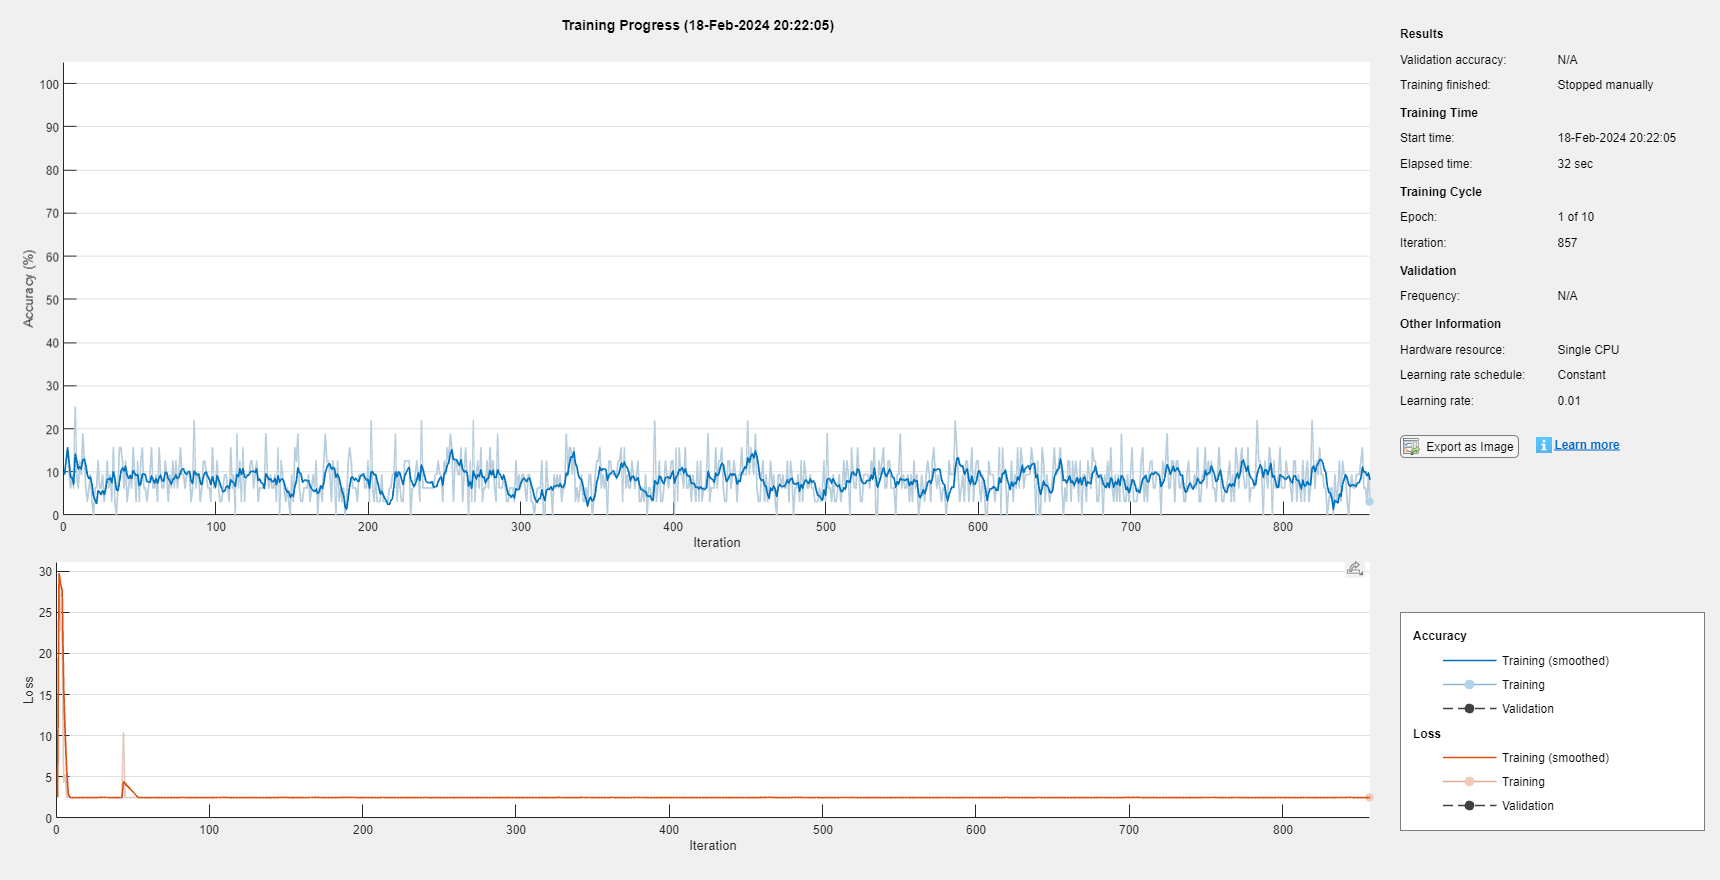

net =   SeriesNetwork with properties:

         Layers: [16×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classoutput'}


net = trainNetwork(dsTrain, layers_G1, options)

dsTrain.read()

ans = 1×2 cell array
    {4032×1 double}    {[5]}


YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = sum(YPred==YValidation)/numel(YValidation)